close all;

% Read file
filename = "2016_pitches_excel2.csv";
tbl = readtable(filename,'TextType','String');

% Convert Pitch Types to categorical
labelName = "Pitch_Type";
tbl = convertvars(tbl,labelName,'categorical');


% Split the columns and display a few rows of the table and pitch types
tbl = splitvars(tbl);
head(tbl)

    Score_Diff    Balls    Strikes    Outs    Pitch_Number    Runner_First    Runner_Second    Runner_Third    Half_Inning       Pitch_Type    
    __________    _____    _______    ____    ____________    ____________    _____________    ____________    ___________    _________________

        0           0         0        0           1               0                0               0               1         Two_Seam_Fastball
        0           0         1        0           2               0                0               0               1         Curveball        
        0           0         2        0           3               0               

classNames = categories(tbl{:,labelName})

classNames = 8×1 cell array
    {'Changeup'            }
    {'Curveball'           }
    {'Four_Seam_Fastball'  }
    {'Intentional_Ball'    }
    {'Slider'              }
    {'Splitter'            }
    {'Two_Seam_Fastball'   }
    {'Unknown_and_Uncommon'}



% Set aside 15% of data for testing
numObservations = size(tbl,1);
numObservationsTrain = floor(0.70*numObservations);
numObservationsTest = numObservations - numObservationsTrain;

% Create an array of random indices and partition 
idx = randperm(numObservations);
idxTrain = idx(1:numObservationsTrain);
idxTest = idx(numObservationsTrain+1:end);

% Partition into training and testing data
tblTrain = tbl(idxTrain,:);
tblTest = tbl(idxTest,:);

% Define a network
numFeatures = size(tbl,2) - 1;
numClasses = numel(classNames);

% Define layers and options
layers = [
    featureInputLayer(numFeatures,"Name","input")
    convolution1dLayer(10,12,"Name","conv1")
    fullyConnectedLayer(100,"Name","fc1")
    batchNormalizationLayer("Name","bn1")
    leakyReluLayer("Name","relu")
    fullyConnectedLayer(50,"Name","fc2")
    batchNormalizationLayer("Name","bn2")
    leakyReluLayer("Name”,“relu2")
    fullyConnectedLayer(numClasses,"Name","fc3")
    softmaxLayer("Name”,“sm")
    classificationLayer];

options = trainingOptions('adam', ...
    'MiniBatchSize',128, ...
    'Shuffle','every-epoch', ...
    'MaxEpochs', 2,'Plots','training-progress', ...
    'Verbose',false);

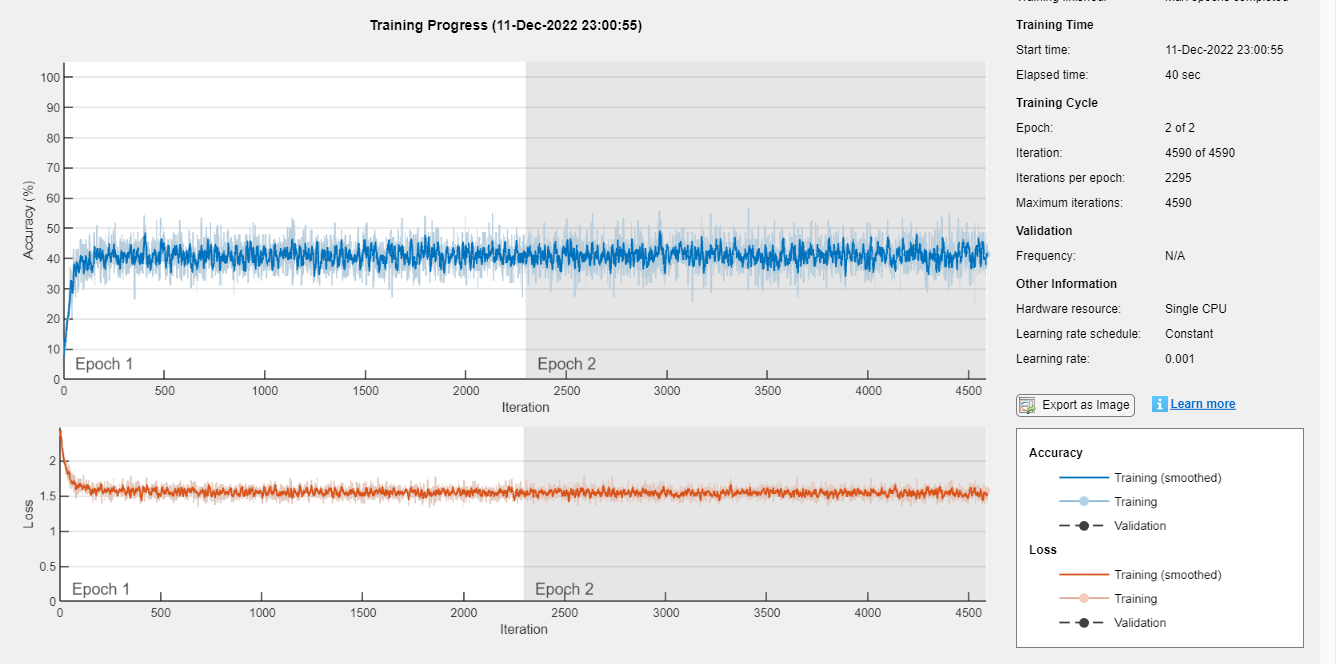


% Train network
net = trainNetwork(tblTrain,layers,options);


% Compute accuracy
YPred = classify(net,tblTest);
YTest = tblTest{:,labelName};

YPred2 = classify(net,tblTrain);
YTrain = tblTrain{:,labelName};

training_accuracy = sum(YPred2 == YTrain)/numel(YTrain)

training_accuracy = 0.4097

testing_accuracy = sum(YPred == YTest)/numel(YTest)

testing_accuracy = 0.4090